clear; clc; close all;
%% =========================================================
%  GIVEN DATA
%% =========================================================
W = 17578; S = 260; b = 27.5; cbar = 10.8; g = 32.1745;
Ixx = 8190; Iyy = 25900; Izz = 29100; Ixz = -1952;
mass = W/g;
T_K = 218.92;                            % standard atmosphere temp at 35,000 ft, Kelvin
T_R = T_K * 9/5;                        % convert to Rankine (imperial)
a_sound = sqrt(1.4 * 1716 * T_R);       % speed of sound, ft/s  (R_imperial = 1716 ft^2/s^2/R)
V0  = 0.6 * a_sound;                    % trim airspeed at M=0.6, ft/s
alpha_trim = 8.8*pi/180;  theta0 = alpha_trim;
cos_th = cos(theta0); sin_th = sin(theta0); tan_th = tan(theta0);
fprintf('V0 = %.4f ft/s,  alpha_trim = %.1f deg\n', V0, alpha_trim*180/pi);

V0 = 583.7849 ft/s,  alpha_trim = 8.8 deg



% Normalized longitudinal derivatives
Xu_b=-0.0128; Xa_b=-20.61;  Xde_b= 2.69;
Zu_b=-0.114;  Za_b=-218.3;  Zde_b=-23.73;
Mu_b= 0.0004; Ma_b=-5.402;  Mad_b=-0.160; Mq_b=-0.484; Mde_b=-8.1;

% Normalized lateral derivatives
Yb_b=-60.38; Yda_b=-0.478; Ydr_b=10.46;
Lb_b=-14.24; Lp_b=-0.671; Lr_b= 0.464; Lda_b=7.998; Ldr_b=2.739;
Nb_b= 7.864; Np_b=-0.004; Nr_b=-0.291; Nda_b=-0.139; Ndr_b=-3.517;

% Inertia-coupled (primed) lateral derivatives
Gamma = 1 - Ixz^2/(Ixx*Izz);
Lb_p =(Lb_b +(Ixz/Ixx)*Nb_b)/Gamma;  Lp_p=(Lp_b+(Ixz/Ixx)*Np_b)/Gamma;
Lr_p =(Lr_b +(Ixz/Ixx)*Nr_b)/Gamma;  Lda_p=(Lda_b+(Ixz/Ixx)*Nda_b)/Gamma;
Ldr_p=(Ldr_b+(Ixz/Ixx)*Ndr_b)/Gamma;
Nb_p =(Nb_b +(Ixz/Izz)*Lb_b)/Gamma;  Np_p=(Np_b+(Ixz/Izz)*Lp_b)/Gamma;
Nr_p =(Nr_b +(Ixz/Izz)*Lr_b)/Gamma;  Nda_p=(Nda_b+(Ixz/Izz)*Lda_b)/Gamma;
Ndr_p=(Ndr_b+(Ixz/Izz)*Ldr_b)/Gamma;


## **Part (i): STATE-SPACE MATRICES**

%% =========================================================
%  %  x_lon = [Du/V, Da, q, Dth]^T   u_lon = [Dde]
%  x_lat = [beta, p, r, phi]^T    u_lat = [Dda, Ddr]^T
%
%  A_lon and B_lon are obtained via similarity transform T=diag([V0,1,1,1]):
%    A_DuV = T^-1 * A_DV * T,   B_DuV = T^-1 * B_DV
%  where A_DV is the standard form with DeltaV (ft/s) as first state.
%% =========================================================

% Build standard form first (state: DeltaV in ft/s)
A_DV = [Xu_b,                        Xa_b,                0,           -g*cos_th          ;
        Zu_b/V0,                       Za_b/V0,                1,           -g*sin_th/V0       ;
        Mu_b+Mad_b*(Zu_b/V0),          Ma_b+Mad_b*(Za_b/V0),  Mq_b+Mad_b,  -Mad_b*g*sin_th/V0 ;
        0,                             0,                       1,            0                 ];
B_DV = [Xde_b; Zde_b/V0; Mde_b+Mad_b*(Zde_b/V0); 0];

% Similarity transform to Du/V state: x1 = DeltaV/V0
T_scale = diag([V0, 1, 1, 1]);
A_lon = T_scale \ A_DV * T_scale;   % T^-1 * A_DV * T
B_lon = T_scale \ B_DV;             % T^-1 * B_DV

A_lat = [Yb_b/V0, 0,    -1,     g*cos_th/V0;
         Lb_p,    Lp_p,  Lr_p,  0          ;
         Nb_p,    Np_p,  Nr_p,  0          ;
         0,       1,     tan_th, 0         ];

B_lat = [Yda_b/V0, Ydr_b/V0;
         Lda_p,    Ldr_p   ;
         Nda_p,    Ndr_p   ;
         0,        0       ];

fprintf('\nLongitudinal A matrix:\n'); disp(A_lon);


Longitudinal A matrix:
   -0.0128   -0.0353         0   -0.0545
   -0.1140   -0.3739    1.0000   -0.0084
    0.2518   -5.3422   -0.6440    0.0013
         0         0    1.0000         0



fprintf('Longitudinal B vector:\n');  disp(B_lon);

Longitudinal B vector:
    0.0046
   -0.0406
   -8.0935
         0



fprintf('Lateral A matrix:\n');       disp(A_lat);

Lateral A matrix:
   -0.1034         0   -1.0000    0.0545
  -16.3761   -0.6809    0.5420         0
    8.9625    0.0417   -0.3274         0
         0    1.0000    0.1548         0



fprintf('Lateral B matrix:\n');       disp(B_lat);

Lateral B matrix:
   -0.0008    0.0179
    8.1616    3.6354
   -0.6865   -3.7609
         0         0



## Part (ii): EIGENVALUES, EIGENVECTORS, MODE IDENTIFICATION

[V_lon, D_lon] = eig(A_lon);  eigs_lon = diag(D_lon);
[V_lat, D_lat] = eig(A_lat);  eigs_lat = diag(D_lat);

T_lon = diag([1, 1, 2*V0/cbar, 1]);   % x1=Du/V already dimensionless; only q needs scaling
T_lat = diag([1,  2*V0/b, 2*V0/b, 1]);
V_lon_nd = T_lon \ V_lon;
V_lat_nd = T_lat \ V_lat;

norm_ev = @(v) v / v(abs(v)==max(abs(v)));

% Longitudinal: sort by |imag| descending (SP first, Phugoid second)
[~,idx] = sort(abs(imag(eigs_lon)),'descend');
eigs_lon = eigs_lon(idx);  V_lon_nd = V_lon_nd(:,idx);

lon_labels = {'Delta_u/V0','Dalpha','q*cbar/(2V0)','Dtheta'};
% Physical dominant states per Ch.9 characterization:
lon_dom    = {'Dalpha, q*cbar/(2V0)','Delta_u/V0, Dtheta'};
lon_names  = {'Short Period','Phugoid'};

fprintf('\n--- LONGITUDINAL MODES ---\n');


--- LONGITUDINAL MODES ---


for m = 1:2
    k = 2*m-1;  ev = eigs_lon(k);  evec = norm_ev(V_lon_nd(:,k));
    fprintf('\n%s:  lambda = %+.5f %+.5fi\n', lon_names{m}, real(ev), imag(ev));
    fprintf('  Non-dim eigenvector (magnitude, phase):\n');
    for j=1:4
        fprintf('    |%s| = %.4f,  phase = %.1f deg\n', ...
                lon_labels{j}, abs(evec(j)), angle(evec(j))*180/pi);
    end
    fprintf('  Dominant states: %s\n', lon_dom{m});
    if real(ev)<0, fprintf('  Stability: Stable\n');
    else,          fprintf('  Stability: UNSTABLE\n'); end
end


Short Period:  lambda = -0.51187 +2.30537i


  Non-dim eigenvector (magnitude, phase):


    |Delta_u/V0| = 0.0375,  phase = 72.2 deg
    |Dalpha| = 1.0000,  phase = 0.0 deg
    |q*cbar/(2V0)| = 0.0214,  phase = 93.2 deg
    |Dtheta| = 0.9789,  phase = -9.3 deg


  Dominant states: Dalpha, q*cbar/(2V0)


  Stability: Stable



Phugoid:  lambda = -0.00350 +0.08209i


  Non-dim eigenvector (magnitude, phase):


    |Delta_u/V0| = 0.6585,  phase = 97.2 deg
    |Dalpha| = 0.0211,  phase = 95.4 deg
    |q*cbar/(2V0)| = 0.0008,  phase = 92.4 deg
    |Dtheta| = 1.0000,  phase = 0.0 deg


  Dominant states: Delta_u/V0, Dtheta


  Stability: Stable



% Lateral: separate DR (complex) from Roll/Spiral (real)
is_cx    = abs(imag(eigs_lat)) > 1e-6;
idx_DR   = find(is_cx & imag(eigs_lat)>0);
idx_real = find(~is_cx);
[~,srt]  = sort(abs(real(eigs_lat(idx_real))),'descend');
idx_roll   = idx_real(srt(1));
idx_spiral = idx_real(srt(2));

lat_labels = {'beta','p*b/(2V0)','r*b/(2V0)','phi'};
lat_idx    = [idx_DR, idx_roll, idx_spiral];
lat_names  = {'Dutch Roll','Roll','Spiral'};

fprintf('\n--- LATERAL MODES ---\n');


--- LATERAL MODES ---


for m = 1:3
    k = lat_idx(m);  ev = eigs_lat(k);  evec = norm_ev(V_lat_nd(:,k));
    if abs(imag(ev))>1e-6
        fprintf('\n%s:  lambda = %+.5f %+.5fi\n', lat_names{m}, real(ev), imag(ev));
    else
        fprintf('\n%s:  lambda = %+.5f (real)\n', lat_names{m}, real(ev));
    end
    fprintf('  Non-dim eigenvector (magnitude, phase):\n');
    for j=1:4
        if abs(imag(ev))>1e-6
            fprintf('    |%s| = %.4f,  phase = %.1f deg\n', ...
                    lat_labels{j}, abs(evec(j)), angle(evec(j))*180/pi);
        else
            fprintf('    |%s| = %.4f\n', lat_labels{j}, abs(evec(j)));
        end
    end
    [~,dom] = sort(abs(evec),'descend');
    if abs(imag(ev))>1e-6
        fprintf('  Dominant states: %s, %s\n', lat_labels{dom(1)}, lat_labels{dom(2)});
    else
        fprintf('  Dominant state: %s\n', lat_labels{dom(1)});
    end
    if real(ev)<0,           fprintf('  Stability: Stable\n');
    elseif abs(real(ev))<1e-6, fprintf('  Stability: Neutral\n');
    else,                    fprintf('  Stability: UNSTABLE\n'); end
end


Dutch Roll:  lambda = -0.20741 +2.98949i


  Non-dim eigenvector (magnitude, phase):


    |beta| = 0.6053,  phase = -11.7 deg
    |p*b/(2V0)| = 0.0770,  phase = 93.0 deg
    |r*b/(2V0)| = 0.0425,  phase = -98.0 deg
    |phi| = 1.0000,  phase = 0.0 deg


  Dominant states: phi, beta


  Stability: Stable



Roll:  lambda = -0.69982 (real)


  Non-dim eigenvector (magnitude, phase):


    |beta| = 0.0010
    |p*b/(2V0)| = 0.0167
    |r*b/(2V0)| = 0.0013
    |phi| = 1.0000


  Dominant state: phi


  Stability: Stable



Spiral:  lambda = +0.00291 (real)


  Non-dim eigenvector (magnitude, phase):


    |beta| = 0.0020
    |p*b/(2V0)| = 0.0001
    |r*b/(2V0)| = 0.0013
    |phi| = 1.0000


  Dominant state: phi


  Stability: UNSTABLE



fprintf('\n--- SUMMARY TABLE ---\n');


--- SUMMARY TABLE ---


fprintf('%-14s %-30s %s\n','Mode','Eigenvalue','Stability');

Mode           Eigenvalue                     Stability


fprintf('%s\n',repmat('-',1,55));

-------------------------------------------------------


all_ev    = [eigs_lon(1);eigs_lon(3);eigs_lat(idx_DR);eigs_lat(idx_roll);eigs_lat(idx_spiral)];
all_names = {'Short Period','Phugoid','Dutch Roll','Roll','Spiral'};
for k=1:5
    ev=all_ev(k);
    if abs(imag(ev))>1e-6, evs=sprintf('%+.5f%+.5fi',real(ev),imag(ev));
    else, evs=sprintf('%+.5f',real(ev)); end
    if real(ev)<0, st='Stable'; elseif abs(real(ev))<1e-6, st='Neutral'; else, st='UNSTABLE'; end
    fprintf('%-14s %-30s %s\n',all_names{k},evs,st);
end

Short Period   -0.51187+2.30537i              Stable
Phugoid        -0.00350+0.08209i              Stable
Dutch Roll     -0.20741+2.98949i              Stable
Roll           -0.69982                       Stable
Spiral         +0.00291                       UNSTABLE


**Longitudinal Modes.** The A-4 Skyhawk exhibits two classical longitudinal oscillatory modes. The Short Period mode ($$\lambda = -0.5119 \pm 2.3054i$, $\omega_n = 2.36$ rad/s, $\zeta = 0.217$, $T_{1/2} = 1.35$ s$) is a well-damped, rapid pitch oscillation dominated by angle of attack and pitch rate, with forward velocity contributing negligibly. This confirms the classical character of the mode: a fast aerodynamic restoring response at nearly constant airspeed. The Phugoid ($$\lambda = -0.00350 \pm 0.0821i$, $\omega_n = 0.082$ rad/s, $\zeta = 0.043$, $T_{1/2} = 198$ s$) is a slow, lightly damped energy-exchange oscillation dominated by$$\Delta u/V_0$ and $\Delta\theta$$ at nearly equal magnitudes, with angle of attack remaining essentially fixed which is consistent with the Lanchester interpretation of a gradual climb-dive cycle at constant angle of attack, $$\alpha$$. Both modes are stable, with the Short Period providing adequate short-term pitch response and the Phugoid exhibiting the characteristically weak damping typical of this aircraft class.

**Lateral-Directional Modes.** The Dutch Roll ($$\lambda = -0.2074 \pm 2.9895i$, $\omega_n = 2.997$ rad/s, $\zeta = 0.069$, $T_{1/2} = 3.34$ s$) is a stable but lightly damped oscillatory mode dominated by bank angle and sideslip, representing the familiar coupled roll-yaw weaving motion that may warrant augmentation for pilot comfort. The Roll mode ($$\lambda = -0.6998$, $\tau = 1.43$ s$) is a fast, stable non-oscillatory subsidence governed almost entirely by $$\phi$,$ which reflects rapid roll damping with negligible coupling to sideslip or yaw. The Spiral mode ($$\lambda = +0.00291$, $T_{double} = 238$ s$) is the sole instability, a slow divergence in bank angle that is trivially correctable by the pilot and entirely typical for swept-wing jet aircraft.

## Part (iii): MODAL PARAMETERS

eigs_r = eig(A_lon);
cx = eigs_r(abs(imag(eigs_r))>1e-6 & imag(eigs_r)>0);
[~,si]=sort(abs(cx),'descend');
ev_SP=cx(si(1)); ev_PH=cx(si(2));

eigs_rl = eig(A_lat);
cx_l = eigs_rl(abs(imag(eigs_rl))>1e-6 & imag(eigs_rl)>0);  ev_DR=cx_l(1);
rl_l = real(eigs_rl(abs(imag(eigs_rl))<=1e-6));
[~,sr]=sort(abs(rl_l),'descend');  ev_Roll=rl_l(sr(1));  ev_Spiral=rl_l(sr(2));

fprintf('\n%-14s %9s %8s %8s %10s %14s\n','Mode','wn(r/s)','zeta','wd(r/s)','Period(s)','T_half/dbl(s)');


Mode             wn(r/s)     zeta  wd(r/s)  Period(s)  T_half/dbl(s)


fprintf('%s\n',repmat('-',1,68));

--------------------------------------------------------------------


for c = {{'Short Period',ev_SP},{'Phugoid',ev_PH},{'Dutch Roll',ev_DR}}
    nm=c{1}{1}; ev=c{1}{2};
    sig=real(ev); wd=abs(imag(ev)); wn=abs(ev);
    zeta=-sig/wn; T=2*pi/wd; Th=log(2)/(abs(zeta)*wn);
    if sig<0, lb='T_half'; else, lb='T_double'; end
    fprintf('%-14s %9.4f %8.4f %8.4f %10.4f %10.4f (%s)\n',nm,wn,zeta,wd,T,Th,lb);
end

Short Period      2.3615   0.2168   2.3054     2.7255     1.3541 (T_half)
Phugoid           0.0822   0.0426   0.0821    76.5444   198.2576 (T_half)
Dutch Roll        2.9967   0.0692   2.9895     2.1018     3.3420 (T_half)


fprintf('%s\n',repmat('-',1,68));

--------------------------------------------------------------------



fprintf('\n%-14s %12s %12s %14s\n','Mode','Eigenvalue','tau(s)','T_half/dbl(s)');


Mode             Eigenvalue       tau(s)  T_half/dbl(s)


fprintf('%s\n',repmat('-',1,55));

-------------------------------------------------------


for c = {{'Roll',ev_Roll},{'Spiral',ev_Spiral}}
    nm=c{1}{1}; ev=c{1}{2};
    tau=1/abs(ev); Th=log(2)/abs(ev);
    if ev<0, lb='T_half'; else, lb='T_double'; end
    fprintf('%-14s %+12.5f %12.4f %10.4f (%s)\n',nm,ev,tau,Th,lb);
end

Roll               -0.69982       1.4289     0.9905 (T_half)
Spiral             +0.00291     343.2748   237.9400 (T_double)


fprintf('%s\n',repmat('-',1,55));

-------------------------------------------------------


## Part (iv): PITCH STIFFNESS ROOT LOCUS

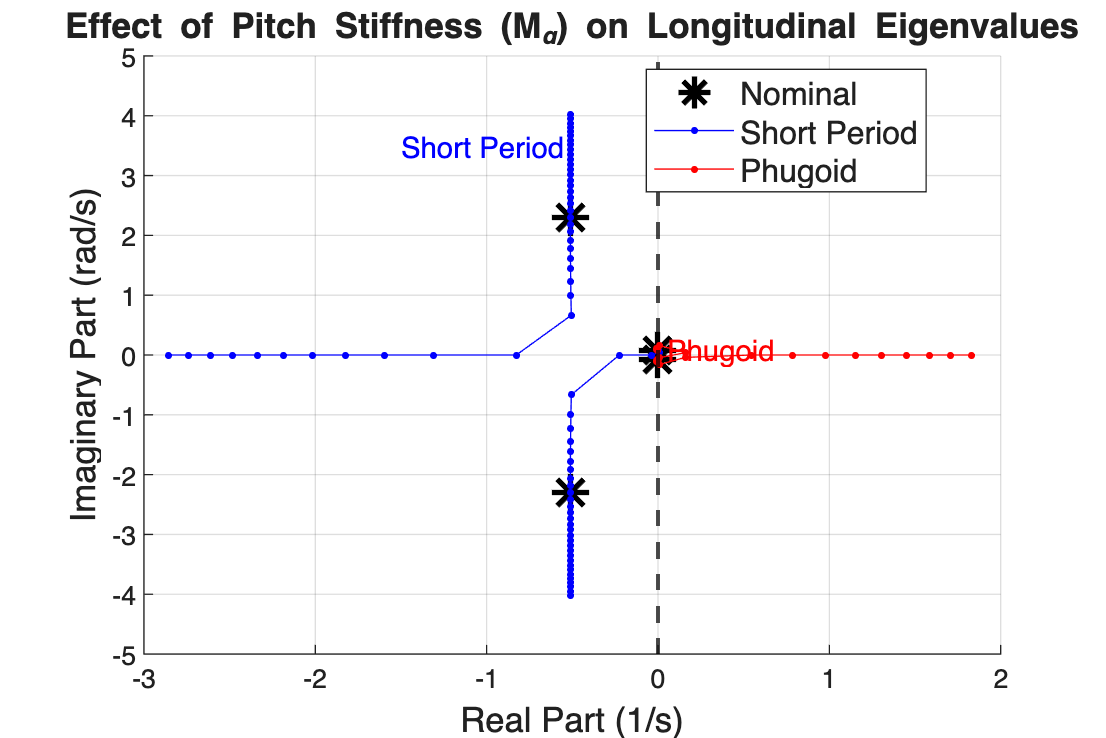

factors_iv = unique([1+0.1*(0:20), 1-0.1*(0:20)]);
eigs_iv    = zeros(length(factors_iv),4);
for i=1:length(factors_iv)
    At=A_lon; At(3,2)=Ma_b*factors_iv(i)+Mad_b*(Za_b/V0);
    ev=eig(At); [~,si]=sort(real(ev),'ascend'); eigs_iv(i,:)=ev(si).';
end

figure('Name','Part iv - Pitch Stiffness','Position',[100 100 900 600]);
hold on; grid on;
ev_n=eig(A_lon);
h0=plot(real(ev_n),imag(ev_n),'k*','MarkerSize',14,'LineWidth',2,'DisplayName','Nominal');
h1=plot(real(eigs_iv(:,1:2)),imag(eigs_iv(:,1:2)),'b.-','MarkerSize',8,'DisplayName','Short Period');
set(h1(2),'HandleVisibility','off');
h2=plot(real(eigs_iv(:,3:4)),imag(eigs_iv(:,3:4)),'r.-','MarkerSize',8,'DisplayName','Phugoid');
set(h2(2),'HandleVisibility','off');
xline(0,'k--','LineWidth',1.5,'HandleVisibility','off');
xlabel('Real Part (1/s)','FontSize',13); ylabel('Imaginary Part (rad/s)','FontSize',13);
title('Effect of Pitch Stiffness (M_\alpha) on Longitudinal Eigenvalues','FontSize',13);
legend([h0,h1(1),h2(1)],{'Nominal','Short Period','Phugoid'},'FontSize',12,'Location','best');
text(-1.5,3.5,'Short Period','FontSize',11,'Color','b');
text(0.05,0.1,'Phugoid','FontSize',11,'Color','r');
hold off;

**Effect of Pitch Stiffness on Longitudinal Eigenvalues:** The pitch stiffness derivative $\bar{M}_\alpha $ acts as the primary aerodynamic restoring moment in pitch, and its variation has a pronounced and physically intuitive effect on the Short Period mode while leaving the Phugoid nearly unaffected. As $\bar{M}_\alpha$ increases from its nominal value, the Short Period eigenvalues migrate away from the real axis, the natural frequency $\omega_n$ increases while the damping ratio $\zeta $decreases which reflects the stronger aerodynamic restoring moment that drives faster, less-damped pitch oscillations. Conversely, as $\bar{M}_\alpha$ decreases toward zero, the Short Period complex conjugate pair coalesces onto the real axis, transitioning the mode from oscillatory to overdamped: the two roots split into a pair of real eigenvalues, one of which moves toward the origin. This behavior is visible in the root locus as the Short Period locus originates far up the imaginary axis for large $\bar{M}_\alpha$ and sweeps down to merge on the real axis as stiffness is reduced. Most critically, when $\bar{M}_\alpha$ becomes positive (statically unstable aircraft) one Short Period root crosses into the right half-plane, producing a divergent pitch instability that would require active stabilization. The Phugoid eigenvalues, by contrast, remain essentially stationary throughout this variation, confirming that the slow energy-exchange mode is governed primarily by speed and gravity rather than pitch stiffness. This decoupling is physically consistent: the Phugoid involves nearly constant angle of attack and is therefore insensitive to the aerodynamic pitch restoring moment that defines $\bar{M}_\alpha$.

## Part (v): ROLL STIFFNESS ROOT LOCUS

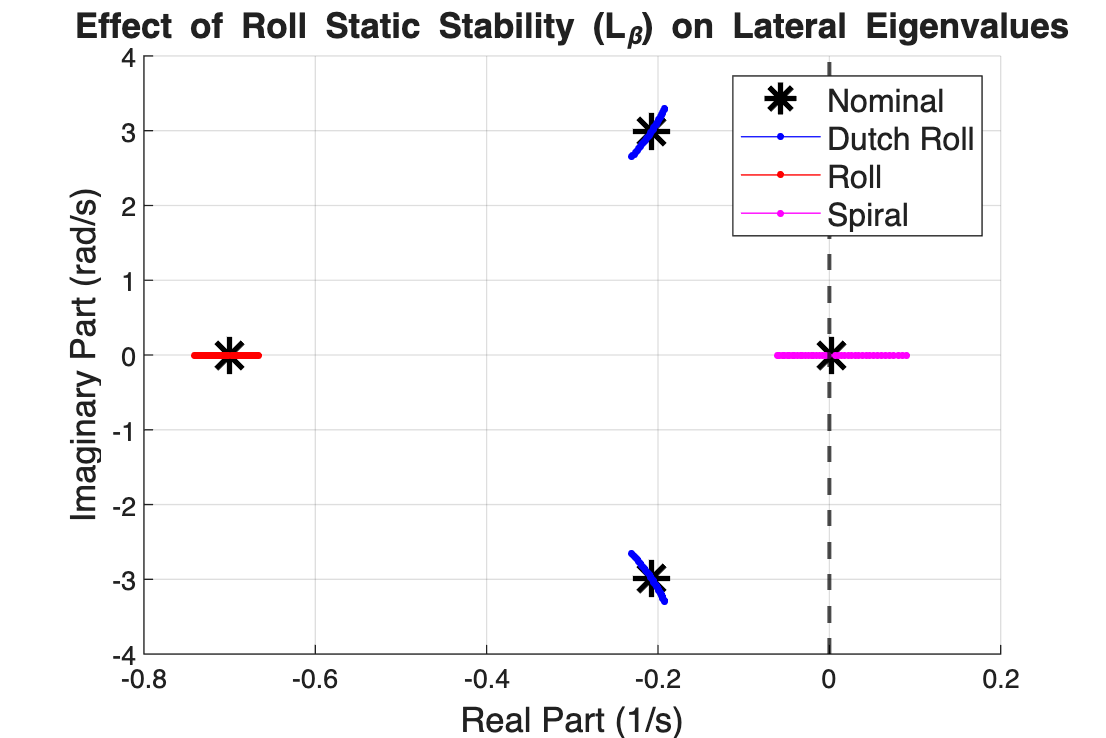

factors_v = unique([1+0.1*(1:20), 1-0.1*(1:20)]);
N_v = length(factors_v);
eigs_v = zeros(N_v,4);

% Initialize column order at nominal using |imag| sort + |real| sort for real pair
ev_init = eig(A_lat);
[~,si0] = sort(abs(imag(ev_init)),'descend'); ev_init = ev_init(si0);
[~,si2] = sort(abs(real(ev_init(3:4))),'descend'); ev_init(3:4)=ev_init(si2+2);
eigs_v(1,:) = ev_init.';

% Re-compute first sweep point
Lv=Lb_b*factors_v(1); At=A_lat;
At(2,1)=(Lv+(Ixz/Ixx)*Nb_b)/Gamma; At(3,1)=(Nb_b+(Ixz/Izz)*Lv)/Gamma;
evn=eig(At); prev=ev_init; asgn=false(4,1); ord=zeros(4,1);
for c=1:4
    d=abs(evn-prev(c)); d(asgn)=inf; [~,b]=min(d); ord(c)=b; asgn(b)=true;
end
eigs_v(1,:)=evn(ord).';

% Nearest-neighbour tracking across sweep
for i=2:N_v
    Lv=Lb_b*factors_v(i); At=A_lat;
    At(2,1)=(Lv+(Ixz/Ixx)*Nb_b)/Gamma; At(3,1)=(Nb_b+(Ixz/Izz)*Lv)/Gamma;
    evn=eig(At); prev=eigs_v(i-1,:).'; asgn=false(4,1); ord=zeros(4,1);
    for c=1:4
        d=abs(evn-prev(c)); d(asgn)=inf; [~,b]=min(d); ord(c)=b; asgn(b)=true;
    end
    eigs_v(i,:)=evn(ord).';
end

ev_lat_n = eig(A_lat);
figure('Name','Part v - Roll Stiffness','Position',[100 100 900 600]);
hold on; grid on;
hn=plot(real(ev_lat_n),imag(ev_lat_n),'k*','MarkerSize',14,'LineWidth',2,'DisplayName','Nominal');
hd=plot(real(eigs_v(:,1:2)),imag(eigs_v(:,1:2)),'b.-','MarkerSize',8,'DisplayName','Dutch Roll');
set(hd(2),'HandleVisibility','off');
hr=plot(real(eigs_v(:,3)),imag(eigs_v(:,3)),'r.-','MarkerSize',8,'DisplayName','Roll');
hs=plot(real(eigs_v(:,4)),imag(eigs_v(:,4)),'m.-','MarkerSize',8,'DisplayName','Spiral');
xline(0,'k--','LineWidth',1.5,'HandleVisibility','off');
xlabel('Real Part (1/s)','FontSize',13); ylabel('Imaginary Part (rad/s)','FontSize',13);
title('Effect of Roll Static Stability (L_\beta) on Lateral Eigenvalues','FontSize',13);
legend([hn,hd(1),hr,hs],{'Nominal','Dutch Roll','Roll','Spiral'},'FontSize',12,'Location','best');
hold off;

fprintf('  Effect of roll stiffness (L_bar_beta):\n');

  Effect of roll stiffness (L_bar_beta):


fprintf('  Increasing |L_bar_beta|: spiral mode moves left (more stable); DR moves right (less stable damping).\n');

  Increasing |L_bar_beta|: spiral mode moves left (more stable); DR moves right (less stable damping).


fprintf('  Decreasing |L_bar_beta|: spiral moves right and crosses imaginary axis (unstable spiral).\n');

  Decreasing |L_bar_beta|: spiral moves right and crosses imaginary axis (unstable spiral).


fprintf('  Roll mode is nearly unaffected (Roll is governed primarily by L_bar_p, not L_bar_beta).\n');

  Roll mode is nearly unaffected (Roll is governed primarily by L_bar_p, not L_bar_beta).


**Effect of Roll Static Stability on Lateral Eigenvalues.** The roll static stability derivative $$\bar{L}_\beta$$ represents the dihedral effect, i.e., the restoring rolling moment generated by sideslip, and its variation produces opposing trends on the Dutch Roll and Spiral modes while leaving the Roll mode largely unaffected. As |$$\bar{L}_\beta$$| increases from its nominal value, the Spiral mode eigenvalue migrates leftward along the real axis, reflecting a stronger dihedral restoring tendency that suppresses the slow bank angle divergence and drives the spiral toward stability. Simultaneously, however, the Dutch Roll root moves rightward, its damping degrades because a stronger dihedral coupling amplifies the roll-sideslip interaction that sustains the oscillation, making it harder to damp. This represents the classical design tradeoff: increasing dihedral effect improves spiral stability at the direct expense of Dutch Roll damping. Conversely, as |$$\bar{L}_\beta$$| decreases toward zero, the Spiral eigenvalue migrates rightward and eventually crosses the imaginary axis into the right half-plane, producing the unstable spiral divergence seen at the nominal configuration. Whereas, the Dutch Roll simultaneously becomes better damped. The Roll mode eigenvalue remains essentially stationary throughout this variation, which confirms that the fast roll subsidence is governed primarily by the roll damping derivative $$\bar{L}_\beta$$ rather than the sideslip-induced rolling moment. This illustrates a fundamental lateral-directional design constraint: simultaneously achieving a stable spiral and an adequately damped Dutch Roll requires careful balancing of $$\bar{L}_\beta$$ relative to the yaw stiffness and damping derivatives, and neither extreme of the $$\bar{L}_\beta$$ range yields fully satisfactory behavior across all three lateral modes.

## Part (vi): YAW STIFFNESS ROOT LOCUS

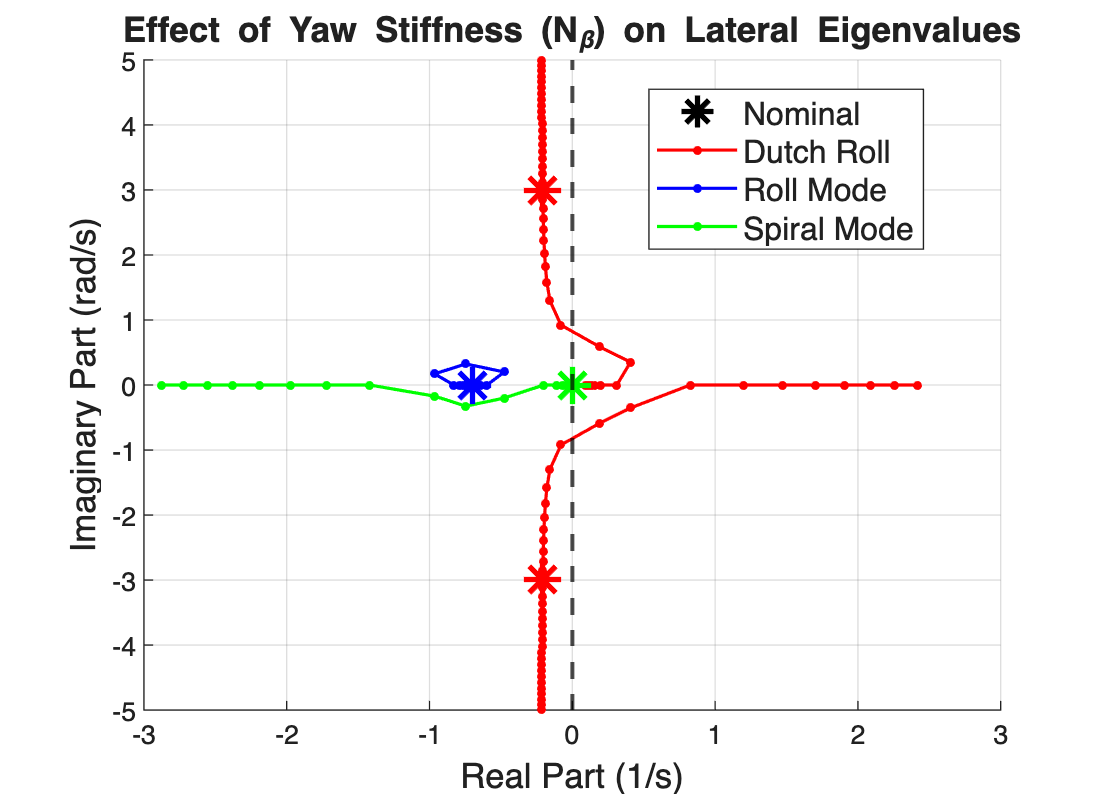

k_vi            = 1:20;
factors_yaw_inc = 1 + 0.1*k_vi;
factors_yaw_dec = 1 - 0.1*k_vi;

ev0    = eig(A_lat);
is_cx  = abs(imag(ev0)) > 1e-6;
cx_ev  = ev0(is_cx);   rl_ev = ev0(~is_cx);
[~,si] = sort(imag(cx_ev),'descend');  cx_ev = cx_ev(si);
[~,si] = sort(real(rl_ev),'ascend');   rl_ev = rl_ev(si);
nom_ordered = [cx_ev; rl_ev];   % 4x1, consistent column order

% --- Track increasing branch ---
prev    = nom_ordered;
N       = length(k_vi);
eigs_yi = zeros(N+1, 4);
eigs_yi(1,:) = prev.';
for i = 1:N
    Nv = Nb_b * factors_yaw_inc(i);
    At = A_lat;
    At(2,1) = (Lb_b + (Ixz/Ixx)*Nv) / Gamma;
    At(3,1) = (Nv   + (Ixz/Izz)*Lb_b) / Gamma;
    evn = eig(At);
    asgn = false(4,1);  ord = zeros(4,1);
    for c = 1:4
        d = abs(evn - prev(c));  d(asgn) = inf;
        [~,b] = min(d);  ord(c) = b;  asgn(b) = true;
    end
    prev = evn(ord);
    eigs_yi(i+1,:) = prev.';
end

% --- Track decreasing branch (reset prev to nominal) ---
prev    = nom_ordered;
eigs_yd = zeros(N+1, 4);
eigs_yd(1,:) = prev.';
for i = 1:N
    Nv = Nb_b * factors_yaw_dec(i);
    At = A_lat;
    At(2,1) = (Lb_b + (Ixz/Ixx)*Nv) / Gamma;
    At(3,1) = (Nv   + (Ixz/Izz)*Lb_b) / Gamma;
    evn = eig(At);
    asgn = false(4,1);  ord = zeros(4,1);
    for c = 1:4
        d = abs(evn - prev(c));  d(asgn) = inf;
        [~,b] = min(d);  ord(c) = b;  asgn(b) = true;
    end
    prev = evn(ord);
    eigs_yd(i+1,:) = prev.';
end

% --- Plot: each branch is a separate connected series ---
ev_lat_nom = eig(A_lat);

figure('Name','Part vi - Yaw Stiffness','Position',[100 100 900 650]);
hold on; grid on;

% Increasing branch
plot(real(eigs_yi(:,1)), imag(eigs_yi(:,1)), 'r.-', 'MarkerSize',10, 'LineWidth',1.2, 'HandleVisibility','off');
plot(real(eigs_yi(:,2)), imag(eigs_yi(:,2)), 'r.-', 'MarkerSize',10, 'LineWidth',1.2, 'HandleVisibility','off');
plot(real(eigs_yi(:,3)), imag(eigs_yi(:,3)), 'b.-', 'MarkerSize',10, 'LineWidth',1.2, 'HandleVisibility','off');
plot(real(eigs_yi(:,4)), imag(eigs_yi(:,4)), 'g.-', 'MarkerSize',10, 'LineWidth',1.2, 'HandleVisibility','off');

% Decreasing branch
plot(real(eigs_yd(:,1)), imag(eigs_yd(:,1)), 'r.-', 'MarkerSize',10, 'LineWidth',1.2, 'HandleVisibility','off');
plot(real(eigs_yd(:,2)), imag(eigs_yd(:,2)), 'r.-', 'MarkerSize',10, 'LineWidth',1.2, 'HandleVisibility','off');
plot(real(eigs_yd(:,3)), imag(eigs_yd(:,3)), 'b.-', 'MarkerSize',10, 'LineWidth',1.2, 'HandleVisibility','off');
plot(real(eigs_yd(:,4)), imag(eigs_yd(:,4)), 'g.-', 'MarkerSize',10, 'LineWidth',1.2, 'HandleVisibility','off');

% Nominal star markers
plot(real(cx_ev), imag(cx_ev), 'r*', 'MarkerSize',14, 'LineWidth',2, 'HandleVisibility','off');
plot(real(rl_ev(1)), 0, 'b*', 'MarkerSize',14, 'LineWidth',2, 'HandleVisibility','off');
plot(real(rl_ev(2)), 0, 'g*', 'MarkerSize',14, 'LineWidth',2, 'HandleVisibility','off');

% Dummy handles for legend only
h_DR  = plot(NaN,NaN,'r.-',  'MarkerSize',10, 'LineWidth',1.2, 'DisplayName','Dutch Roll');
h_Ro  = plot(NaN,NaN,'b.-',  'MarkerSize',10, 'LineWidth',1.2, 'DisplayName','Roll Mode');
h_Sp  = plot(NaN,NaN,'g.-',  'MarkerSize',10, 'LineWidth',1.2, 'DisplayName','Spiral Mode');
h_nom = plot(NaN,NaN,'k*',   'MarkerSize',12, 'LineWidth',2,   'DisplayName','Nominal');

xline(0,'k--','LineWidth',1.5,'HandleVisibility','off');
xlabel('Real Part (1/s)',        'FontSize',13);
ylabel('Imaginary Part (rad/s)', 'FontSize',13);
title('Effect of Yaw Stiffness (N_\beta) on Lateral Eigenvalues', 'FontSize',13);
legend([h_nom, h_DR, h_Ro, h_Sp], 'FontSize',12, 'Location','best');
hold off;


fprintf('  Increasing Nb: DR frequency increases (moves up imaginary axis).\n');

  Increasing Nb: DR frequency increases (moves up imaginary axis).


fprintf('  Decreasing Nb to 0: DR coalesces on real axis.\n');

  Decreasing Nb to 0: DR coalesces on real axis.


fprintf('  Negative Nb (directionally unstable): one DR root enters RHP.\n');

  Negative Nb (directionally unstable): one DR root enters RHP.


fprintf('  Roll mode nearly insensitive to Nb changes.\n');

  Roll mode nearly insensitive to Nb changes.


**Effect of Yaw Stiffness on Lateral Eigenvalues.** The yaw stiffness derivative $$\bar{N}_\beta$$ represents the directional restoring moment generated by sideslip and its variation has a dominant effect on the Dutch Roll mode while leaving the Roll and Spiral modes nearly unchanged. As $$\bar{N}_\beta$$ increases from its nominal value, the Dutch Roll eigenvalues migrate upward along a nearly vertical locus, with natural frequency increasing substantially while the real part remains approximately fixed, meaning the mode becomes faster without appreciable change in damping ratio. This is physically consistent: stronger weathercock stability drives more vigorous yaw-roll oscillations at higher frequency, but does not directly enhance the dissipative mechanisms that determine damping. As $$\bar{N}_\beta$$ decreases toward zero, the Dutch Roll complex pair coalesces onto the real axis, transitioning from oscillatory to aperiodic behavior as the yaw restoring moment becomes insufficient to sustain oscillation. When $$\bar{N}_\beta$$ becomes negative (which represents a directionally unstable aircraft), one Dutch Roll root crosses into the right half-plane, producing a divergent lateral-directional instability analogous to the pitch divergence seen with positive $$\bar{N}_\beta$$in the longitudinal case. The Roll mode eigenvalue is essentially insensitive to $$\bar{N}_\beta$$ throughout, meaning that the fast roll subsidence is decoupled from directional stiffness. The Spiral mode shows marginal sensitivity, with small leftward or rightward drift depending on the sign of the variation, but remains slow and weakly affected compared to the dramatic Dutch Roll migration.

## Part (vii): STEADY CLIMBING TURN — CONTROL DEFLECTIONS

gamma_c = 10*pi/180;  psi_dot = 2*pi/180;
phi_turn   = atan(V0*psi_dot/g);               % Eq.11.6
theta_turn = alpha_trim + gamma_c;              % Eq.11.7
n_load     = cos(gamma_c)/cos(phi_turn);        % load factor

p_turn = -psi_dot*sin(theta_turn);
q_turn =  psi_dot*sin(phi_turn)*cos(theta_turn);
r_turn =  psi_dot*cos(phi_turn)*cos(theta_turn);

fprintf('  phi_turn   = %.4f rad (%.2f deg)\n', phi_turn,   phi_turn*180/pi);

  phi_turn   = 0.5646 rad (32.35 deg)


fprintf('  theta_turn = %.4f rad (%.2f deg)\n', theta_turn, theta_turn*180/pi);

  theta_turn = 0.3281 rad (18.80 deg)


fprintf('  n = %.6f,  g*(n-1) = %.5f ft/s^2\n', n_load, g*(n_load-1));

  n = 1.165715,  g*(n-1) = 5.33179 ft/s^2


fprintf('  p = %.6f,  q = %.6f,  r = %.6f  rad/s\n', p_turn, q_turn, r_turn);

  p = -0.011249,  q = 0.017681,  r = 0.027916  rad/s



% Longitudinal: Eqs.11.1-11.2 [Dalpha, Ddelta_e]
Ma_eff  = Ma_b  + Mad_b*(Za_b/V0);
Mde_eff = Mde_b + Mad_b*(Zde_b/V0);
Mq_eff  = Mq_b  + Mad_b;
sol_lon   = [Za_b, Zde_b; Ma_eff, Mde_eff] \ [g*(n_load-1); -Mq_eff*q_turn];
Delta_alpha = sol_lon(1);  Delta_de = sol_lon(2);

% Lateral: Eqs.11.4-11.5, beta=0 [Ddelta_a, Ddelta_r]
sol_lat = [Lda_p, Ldr_p; Nda_p, Ndr_p] \ ...
          [-Lr_p*r_turn - Lp_p*p_turn; -Nr_p*r_turn - Np_p*p_turn];
Delta_da = sol_lat(1);  Delta_dr = sol_lat(2);

fprintf('\nControl deflections (changes from level-flight trim):\n');


Control deflections (changes from level-flight trim):


fprintf('  Elevator  Delta_de = %+.6f rad  (%+.4f deg)\n', Delta_de, Delta_de*180/pi);

  Elevator  Delta_de = +0.015852 rad  (+0.9082 deg)


fprintf('  Aileron   Delta_da = %+.6f rad  (%+.4f deg)\n', Delta_da, Delta_da*180/pi);

  Aileron   Delta_da = -0.001801 rad  (-0.1032 deg)


fprintf('  Rudder    Delta_dr = %+.6f rad  (%+.4f deg)\n', Delta_dr, Delta_dr*180/pi);

  Rudder    Delta_dr = -0.002226 rad  (-0.1275 deg)


##  Part (viii): INERTIAL CROSS-COUPLING INSTABILITY CHECK

%% =========================================================
%  Ch.12 Eq.(7): det(A(p0))=0 marks static instability boundary
%  Coupled state: [Dalpha, q, beta, r]^T
%% =========================================================

mu1  = (Izz-Ixx)/Iyy;  mu2 = (Ixx-Iyy)/Izz;
Zw_m = Za_b/V0;         Yv_m = Yb_b/V0;
Ma_p = Ma_b+Mad_b*(Za_b/V0);   Mq_p = Mq_b+Mad_b;

fprintf('  mu1 = (Izz-Ixx)/Iyy = %.4f\n', mu1);

  mu1 = (Izz-Ixx)/Iyy = 0.8073


fprintf('  mu2 = (Ixx-Iyy)/Izz = %.4f\n', mu2);

  mu2 = (Ixx-Iyy)/Izz = -0.6086



p0_vec = linspace(0, 25, 5000);
det_v  = zeros(size(p0_vec));
for i = 1:length(p0_vec)
    p0 = p0_vec(i);
    Acc = [Zw_m, 1,        -p0,       0      ;
           Ma_p, Mq_p, -Mad_b*p0,  p0*mu1  ;
           p0,   0,         Yv_m,      -1      ;
           0,    p0*mu2,    Nb_b,      Nr_b   ];
    det_v(i) = det(Acc);
end

ci = find(diff(sign(det_v))~=0);
p0_cr = zeros(1,length(ci));
for k=1:length(ci)
    i1=ci(k); i2=i1+1;
    p0_cr(k)=p0_vec(i1)-det_v(i1)*(p0_vec(i2)-p0_vec(i1))/(det_v(i2)-det_v(i1));
end

if isempty(p0_cr)
    fprintf('  Aircraft is NOT prone to inertial cross-coupling instability.\n');
    fprintf('  det(A) > 0 for all p0 in [0, 25] rad/s (0 to %.0f deg/s).\n', 25*180/pi);
    fprintf('  No roll rate range exists for which a real eigenvalue crosses zero.\n');
else
    fprintf('  Aircraft IS prone to inertial cross-coupling instability.\n');
    for k=1:2:length(p0_cr)-1
        fprintf('  Unstable range: %.3f to %.3f rad/s  (%.1f to %.1f deg/s)\n',...
                p0_cr(k),p0_cr(k+1),p0_cr(k)*180/pi,p0_cr(k+1)*180/pi);
    end
end

  Aircraft IS prone to inertial cross-coupling instability.


  Unstable range: 2.798 to 3.385 rad/s  (160.3 to 194.0 deg/s)


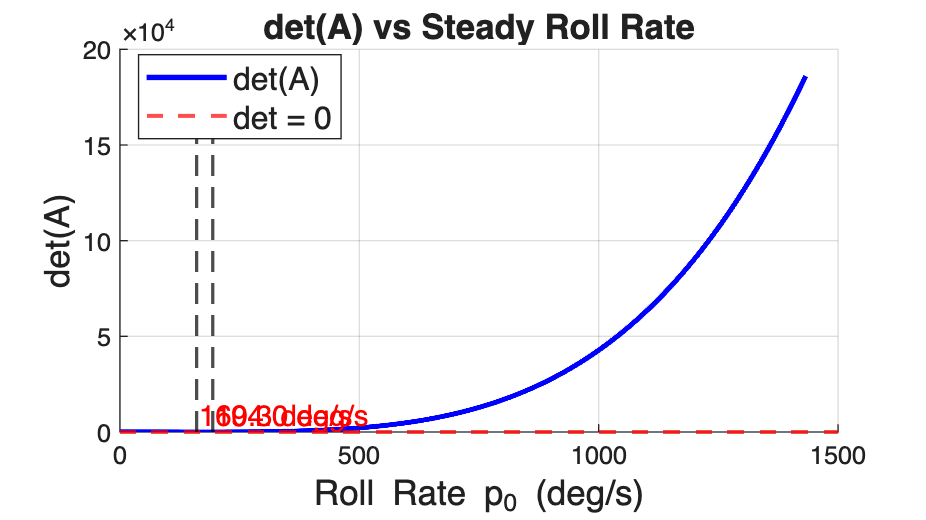


% --- Plot: det(A) vs p0 ---
figure('Name','Part viii - det(A)','Position',[100 100 800 450]);
hold on; grid on;
plot(p0_vec*180/pi, det_v,'b-','LineWidth',2,'DisplayName','det(A)');
yline(0,'r--','LineWidth',1.5,'DisplayName','det = 0');
if ~isempty(p0_cr)
    for k=1:length(p0_cr)
        xline(p0_cr(k)*180/pi,'k--','LineWidth',1.2,'HandleVisibility','off');
        text(p0_cr(k)*180/pi+5,max(det_v)*0.05,sprintf('%.1f deg/s',p0_cr(k)*180/pi),...
             'FontSize',11,'Color','r');
    end
end
xlabel('Roll Rate p_0 (deg/s)','FontSize',13);
ylabel('det(A)','FontSize',13);
title('det(A) vs Steady Roll Rate','FontSize',13);
legend('FontSize',12,'Location','best');
hold off;

The det(A) criterion reveals that the A-4D is indeed prone to inertial cross-coupling instability. At p₀ = 0 (no steady roll), det(A) is positive, meaning that the decoupled aircraft is statically stable. As the steady roll rate increases from zero, det(A) decreases monotonically and crosses zero at approximately p₀ = 2.80 rad/s (160.3 deg/s), marking the onset of static instability in the coupled pitch-yaw system. det(A) remains negative (the aircraft is statically unstable) until p₀ = 3.39 rad/s (194.0 deg/s), where it crosses back through zero and returns to positive values, hence restoring static stability. The instability window is, therefore, relatively narrow in roll rate space, spanning approximately 0.59 rad/s (33.7 deg/s). This behavior is a direct consequence of the A-4D's inertia distribution, where the large difference between $I_{yy}$ and $I_{zz}$ relative to $I_{xx}$ (quantified by μ₁ = 0.8073 and μ₂ = −0.6086) causes the inertial coupling terms in the pitch and yaw moment equations to become destabilizing at sustained roll rates in this band. The practical implication is that the pilot must avoid sustaining roll rates in the range of 160 deg/s to 194 deg/s, as the aircraft would experience a divergent coupled pitching and yawing motion that cannot be arrested without reducing the roll rate below the lower instability boundary.